% load the data
%LFP = load('C:\Users\Trisha\Desktop\Data\122016 EMG mouse2\VoltageRecording-12172016-1959-005\VoltageRecording-12172016-1959-005_Cycle00001_VoltageRecording_001.csv');


LFP = CT1

LFP = 1893260×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


%Data matrix needs to be called LFP

%downsample
data = LFP(:,2);
% data = LFP(6600000:7200000,2);
 
% setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product %02-13-17 changed from 2.5 to 3
K = 9; % the number of tapers, K = 2*TW - 1 %02-13-17 changed from 3 to 4
params.tapers = [TW K]; 

% frequency spectrum
[S,f] = mtspectrumc(data,params);
'S is'

ans = 'S is'

S

S = 209716×1 single column vector
    0.0346
    0.0347
    0.0325
    0.0316
    0.0302
    0.0246
    0.0009
    0.0010
    0.0009
    0.0014



'f is'

ans = 'f is'

f

f =          0    0.0005    0.0010    0.0014    0.0019    0.0024    0.0029    0.0033    0.0038    0.0043    0.0048    0.0052    0.0057    0.0062    0.0067    0.0072    0.0076    0.0081    0.0086    0.0091    0.0095    0.0100    0.0105    0.0110    0.0114    0.0119    0.0124    0.0129    0.0134    0.0138    0.0143    0.0148    0.0153    0.0157    0.0162    0.0167    0.0172    0.0176    0.0181    0.0186    0.0191    0.0196    0.0200    0.0205    0.0210    0.0215    0.0219    0.0224    0.0229    0.0234


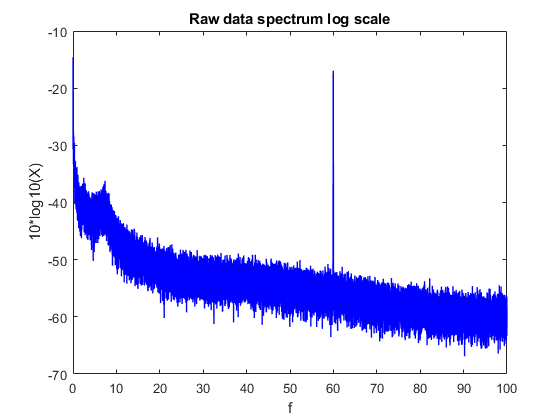


figure; plot_vector(S,f); title('Raw data spectrum log scale');

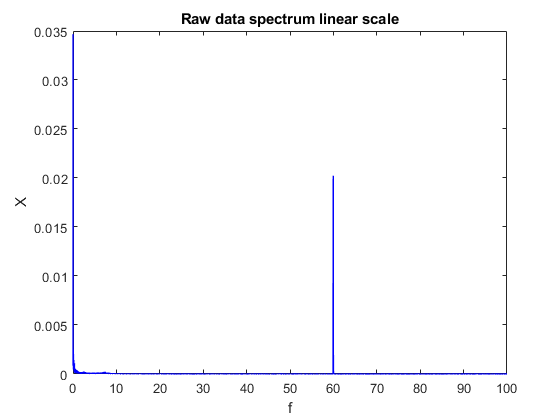

figure; plot_vector(S,f,'n'); title('Raw data spectrum linear scale')%linear scale


%spectrogeam no average
movingwin = [5 .5]

movingwin =     5.0000    0.5000



[S1, t1, f1] = mtspecgramc(data,movingwin,params)

S1 =     0.4678    0.4953    0.4317    0.4755    0.4788    0.4440    0.4897    0.3102    0.2464    0.0613    0.0609    0.0654    0.0622    0.0760    0.0433    0.0432    0.0516    0.0385    0.0349    0.0340    0.0351    0.0312    0.0293    0.0256    0.0225    0.0222    0.0228    0.0224    0.0286    0.0281    0.0400    0.0307    0.0320    0.0312    0.0303    0.0300    0.0296    0.0332    0.0336    0.0394    0.0471    0.0445    0.0454    0.0448    0.0459    0.0464    0.0400    0.0478    0.0696    0.0929
    0.4591    0.4794    0.4725    0.4493    0.4589    0.4169    0.4416    0.2912    0.2532    0.1400    0.0779    0.0714    0.0663    0.0623    0.0538    0.0484    0.0490    0.0394    0.0336    0.0350    0.0282    0.0274    0.0248    0.0187    0.0175    0.0201    0.0205    0.0238    0.0240    0.0264    0.0306    0.0298    0.0308    0.0311    0.0310    0.0296    0.0295    0.0339    0.0333    0.0400    0.0452    0.0437    0.0452    0.0496    0.0499    0.0481    0.0385    0.0436    0.0588    

t1 = 	1.0e+03 *

    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245    0.0250    0.0255    0.0260    0.0265    0.0270


f1 =          0    0.1221    0.2441    0.3662    0.4883    0.6104    0.7324    0.8545    0.9766    1.0986    1.2207    1.3428    1.4648    1.5869    1.7090    1.8311    1.9531    2.0752    2.1973    2.3193    2.4414    2.5635    2.6855    2.8076    2.9297    3.0518    3.1738    3.2959    3.4180    3.5400    3.6621    3.7842    3.9063    4.0283    4.1504    4.2725    4.3945    4.5166    4.6387    4.7607    4.8828    5.0049    5.1270    5.2490    5.3711    5.4932    5.6152    5.7373    5.8594    5.9814


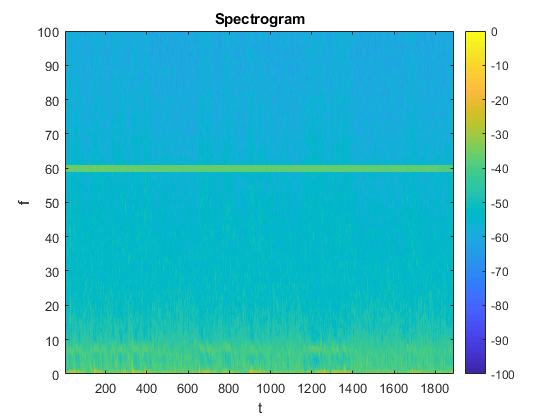

figure; plot_matrix(S1,t1,f1); caxis([-100 0])




win = 10 % length in seconds to average over

win = 10


segave = 1 

segave = 1

[S,f]=mtspectrumsegc(data,win,params,segave)

S = 1639×1 single column vector
    0.0013
    0.0013
    0.0013
    0.0013
    0.0012
    0.0012
    0.0011
    0.0010
    0.0006
    0.0004


f =          0    0.0610    0.1221    0.1831    0.2441    0.3052    0.3662    0.4272    0.4883    0.5493    0.6104    0.6714    0.7324    0.7935    0.8545    0.9155    0.9766    1.0376    1.0986    1.1597    1.2207    1.2817    1.3428    1.4038    1.4648    1.5259    1.5869    1.6479    1.7090    1.7700    1.8311    1.8921    1.9531    2.0142    2.0752    2.1362    2.1973    2.2583    2.3193    2.3804    2.4414    2.5024    2.5635    2.6245    2.6855    2.7466    2.8076    2.8687    2.9297    2.9907


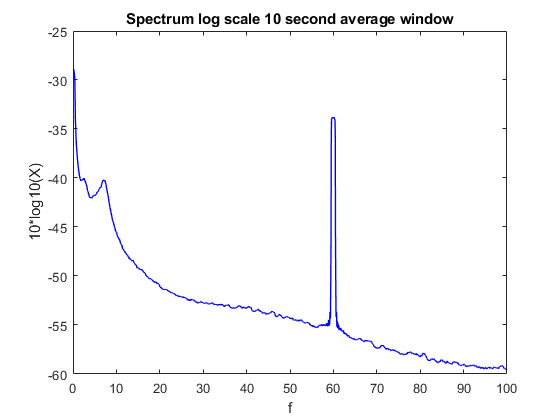

figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); 







%{
% removing 60 Hz
alpha = 0.999; 
omega = 2*pi*60/params.Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];
datano60 = filter(num,den,data);
[S,f] = mtspectrumc(datano60,params);
figure; plot_vector(S,f); title('Spectrum after 60 Hz notch');

% compute spectogram
movingwin = [5 .5]; % Larger window sizes = more frequency bands. Larger step sizes, more blurring > used to use [10 .5], better would be [20 1]
[S1,t,f] = mtspecgramc(data,movingwin,params);
[S2,t,f] = mtspecgramc(datano60,movingwin,params);
   
figure;
subplot(2,1,1);plot_matrix(S1,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); title('before notch');ylim([0 100]);
subplot(2,1,2);plot_matrix(S2,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; title('after notch');ylim([0 100]); caxis([-50 50]);

figure;
subplot(2,1,1);plot_matrix(S1,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); title('before notch');ylim([0 10]);
subplot(2,1,2);plot_matrix(S2,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; title('after notch');ylim([0 10]); caxis('auto');



figure;
plot_matrix(S2,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); colormap jet; colorbar; title('After Notch from 0 to 20 hz');ylim([0 20]);

%}

%{
%1278 to 1288
start = 1 ; %start and end of time to display in seconds
last = 3600;

[~,start] = min(abs(t-start)); %find index of t that contains the time closest to 'start' and 'last'
[~,last] = min(abs(t-last)); 

figure;
ha(1) = subplot(3,1,1); plot(LFP(t(start)*1000:t(last)*1000,1)/1000, data(t(start)*1000:t(last)*1000)); colormap jet; colorbar; title('02-17-17 c2776717');
xlabel('seconds'); ylabel('Volt');
ha(2) = subplot(3,1,2);plot_matrix(S2(start:last,:),t(start:last),f);
xlabel('seconds'); ylabel('Frequency Hz');ylim([0 100]);
ha(3) = subplot(3,1,3);plot_matrix(S2(start:last,:),t(start:last),f);
xlabel('seconds'); ylabel('Frequency Hz'); title('after notch');ylim([0 20]); caxis([-80 0]);
linkaxes(ha, 'x');

%1278 to 1288
start = 1278 ; %start and end of time to display in seconds
last = 1288;

[~,start] = min(abs(t-start)); %find index of t that contains the time closest to 'start' and 'last'
[~,last] = min(abs(t-last)); 

figure;
ha(1) = subplot(2,1,1); plot(LFP(t(start)*1000:t(last)*1000,1)/1000, data(t(start)*1000:t(last)*1000)); colormap jet; colorbar; title('02-17-17 c2776717');
xlabel('seconds'); ylabel('Volt');
ha(2) = subplot(2,1,2);plot_matrix(S2(start:last,:),t(start:last),f);
xlabel('seconds'); ylabel('Frequency Hz');ylim([0 20]);
linkaxes(ha, 'x');





start = 530;
last = 550;
[~,start] = min(abs(t-start));
[~,last] = min(abs(t-last)); 
figure;
ha(1) = subplot(3,1,1); plot(LFP(t(start)*1000:t(last)*1000,1)/1000, data(t(start)*1000:t(last)*1000)); ylim([-.75 -.55]); title('02-16-17 c2776717');
xlabel('ms'); ylabel('Volt');
ha(2) = subplot(3,1,2);plot_matrix(S2(start:last,:),t(start:last),f);
xlabel('seconds'); ylabel('Frequency Hz'); ;ylim([0 100]);
ha(3) = subplot(3,1,3);plot_matrix(S2(start:last,:),t(start:last),f);
xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; ylim([0 10]); caxis;
linkaxes(ha, 'x');


%}

% figure;
% subplot(2,1,1);plot_matrix(S2,t,f);
% xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; title('after notch');ylim([0 20]); caxis([:]);
% subplot(2,1,2);
% plot(data)
% xlabel('seconds'); ylabel('Frequency Hz'); title('before notch');
% 
% figure;
% subplot(2,1,1);
% plot_matrix(S2,t,f);
% subplot(2,1,2);
% plot(times,data)



%compute coherence
% params.err = [1 0.05];
% data1 = datano60(1:10000);
% data2 = datano60(20000:30000);
% [C,phi,S12,S1,S2,f] = coherencycpt(data1,data2,params);
% C - the magnitude of the coherency
% phi - the phase of the coherency;
% S1 and S2 - the spectra for the two signals
% f, the frequency grid used for the calculations;

% figure;plot(f,C);